# Domaci 2 - Regulator po stanjima

Sistem je opisan funkcijom prenosa

$G(s) = \frac{1}{(s + 1)^3}$, 

odnosno u prostoru stanja kao

$\dot{x_1} = x2 \\
\dot{x_2} = x3 \\
\dot{x_3} = -x_1 - 3x_2 - 3x_3 + u  $.

A = [0 1 0; 0 0 1; -1 -3 -3];   %Matrica dinamike stanja
B = [0; 0; 1];                  %Matrica ulaza
C = [1, 0, 0];                  %Matrica izlaza
D = 0;                          %Matrica direktnog prenosa

sys = ss(A, B, C, D);
T = 1e-3; umax = 1; umin = -umax; %Parametri sistema

## Podešavanje parametara regulatora.

Koristi se aproksimacija sistema drugog reda kako bi se podesilo **vreme smirenja** i **oscilatornost** proces u zatvorenoj povratnoj sprezi. S obzirom da realni deo polova zavisi samo od vremena smirenja, greška u ustaljenom stanju zavisi od vremena smirenja. 

Koristi se zakon upravljanja koji je dat sa

$u = -\textbf{K}x$, 

gde je $\textbf{K}$ matrica pojačanja regulatora. 

Ts = 5;
Ksi = 0.9;
w0 = 5/ ( Ts * Ksi);

p = [-10, -Ksi * w0 + 1i * w0 * sqrt(1 - Ksi^2), -Ksi * w0 - 1i * w0 * sqrt(1 - Ksi^2)];               %Zeljeni polovi
fd = poly(p);

K = acker(A, B, p);  

## Provera položaja polova u zatvorenoj povratnoj sprezi.

s = tf('s');
Gcl =  C * inv(s*eye(size(A)) - (A - B*K)) * B + D;
Gcl_2ord = tf([0 dcgain(Gcl)], poly([-Ksi * w0 + 1i * w0 * sqrt(1 - Ksi^2), -Ksi * w0 - 1i * w0 * sqrt(1 - Ksi^2)]));

%Provera polova
p_cl = pole(Gcl);

[~ , i] = min(abs(real(p_cl)));
dom_poles = p_cl(i, 1);

tau = 1/abs(real(dom_poles));
Ts_cl = 5 * tau;
Ksi_cl = abs(real(dom_poles)) / abs(dom_poles);

## Simulacija i prikaz odziva sistema za različite vrednosti parametra regulatora.

Na grafiku ispod vidimo da greška između referentne i stvarne vrednosti u ustaljenom stanju zavisi iskljucivo od vremenske konstante, odnosno pojačanja $k_1$.Takođe, kroz analizu ponašanja u ustaljenom stanju, pri zakonu upravljanja $u = -\textbf{K}x +\textbf{K}_0r(t), R(s) = \frac{r_0}{s} $ i poremećaju $D(s) = \frac{d_0}{s}$, sistema putem


$$ Yss = \lim_{s \rightarrow 0} sY(s) = R_0\frac{N}{1 + k_1} + \frac{D_0}{1 + k_1}.$$


možemo to i matematički potvrditi ukoliko postavimo da je $N = 1+k_1$.

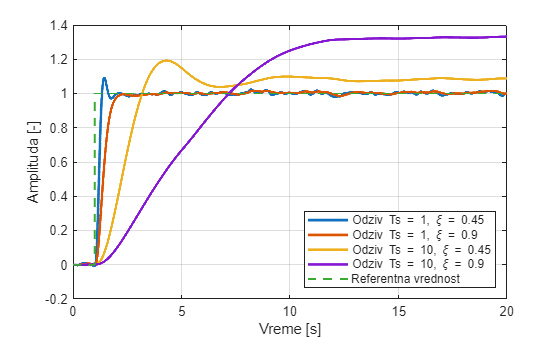

close all;
reg_type = 1; % 1 - cont. , 0 - disc
sat_off = 1; % 1 - off, 0 - on

Tss = [1, 10];
Ksis = [0.45, 0.9];
for Ts = Tss
    for Ksi = Ksis
        w0 = 5/ ( Ts * Ksi);
        
        p = [-10, -Ksi * w0 + 1i * w0 * sqrt(1 - Ksi^2), -Ksi * w0 - 1i * w0 * sqrt(1 - Ksi^2)];   
        fd = poly(p);
        K = acker(A, B, p);
        [y, u, d, r, t] = simulate_step_input(1, 1, 1);

        plot(t, y(:, 1), "LineWidth", 2, "DisplayName", "Odziv Ts = " + num2str(Ts) + ", \xi = " + num2str(Ksi));
        %legend("Odziv Ts = " + num2str(Ts) + ", \xi = " + num2str(Ksi));

        hold on;
    end
end
plot(t, r, "LineStyle", "--", "LineWidth", 1.5, "DisplayName", "Referentna vrednost"); %Referentna vrednost
%yline(1/(1 + K(1, 1)), "LineStyle", "--", "LineWidth", 1.5, "DisplayName",
%"1/(1 + k_1)") %Ukoliko ima samo greška sistem konvergira u ovu vrednost
xlabel("Vreme [s]");
ylabel("Amplituda [-]");
grid on; legend show; legend("Location","southeast") % Vidimo da za vece Ts -> k1 manje, pa je ess vece.

### Simulacija - Konstanta greška pri $r(t) = 0$.

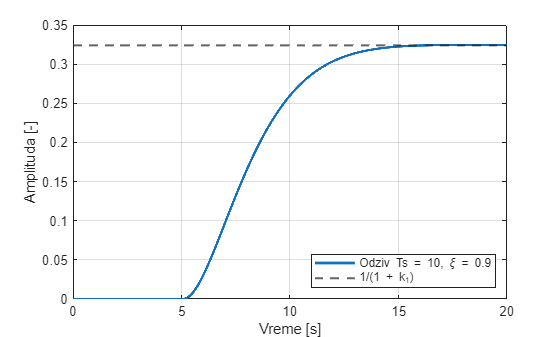

close all;
reg_type = 1; % 1 - cont. , 0 - disc
sat_off = 1; % 1 - off, 0 - on

Tss = [10];
Ksis = [0.9];
for Ts = Tss
    for Ksi = Ksis
        w0 = 5/ ( Ts * Ksi);
        
        p = [-10, -Ksi * w0 + 1i * w0 * sqrt(1 - Ksi^2), -Ksi * w0 - 1i * w0 * sqrt(1 - Ksi^2)];   
        fd = poly(p);
        K = acker(A, B, p);
        [y, u, d, r, t] = simulate_step_input(0, 1, 0);

        plot(t, y(:, 1), "LineWidth", 2, "DisplayName", "Odziv Ts = " + num2str(Ts) + ", \xi = " + num2str(Ksi));
        %legend("Odziv Ts = " + num2str(Ts) + ", \xi = " + num2str(Ksi));

        hold on;
    end
end
%plot(t, r, "LineStyle", "--", "LineWidth", 1.5, "DisplayName", "Referentna vrednost"); %Referentna vrednost
yline(1/(1 + K(1, 1)), "LineStyle", "--", "LineWidth", 1.5, "DisplayName","1/(1 + k_1)") %Ukoliko ima samo greška sistem konvergira u ovu vrednost
xlabel("Vreme [s]");
ylabel("Amplituda [-]");
grid on; legend show; legend("Location","southeast") 

### Simulacija - Uticaj šuma za različite vrednosti pojacanja regulatora.

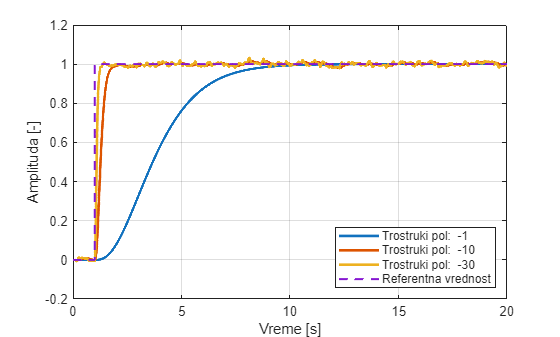

close all;
reg_type = 1; % 1 - cont. , 0 - disc
sat_off = 1; % 1 - off, 0 - on


ps = [-1, -10, -30];
for p = ps
    K = acker(A, B, [p, p, p]);
    [y, u, d, r, t] = simulate_step_input(1, 0, 1);
    plot(t, y(:, 1), "LineWidth", 2, "DisplayName", "Trostruki pol:  " + num2str(p)); hold on;
end



plot(t, r, "LineStyle", "--", "LineWidth", 1.5, "DisplayName", "Referentna vrednost"); %Referentna vrednost
xlabel("Vreme [s]");
ylabel("Amplituda [-]");
grid on; legend show; legend("Location","southeast") 

### Simulacija - Nelinearna saturacija izvrsnog organa

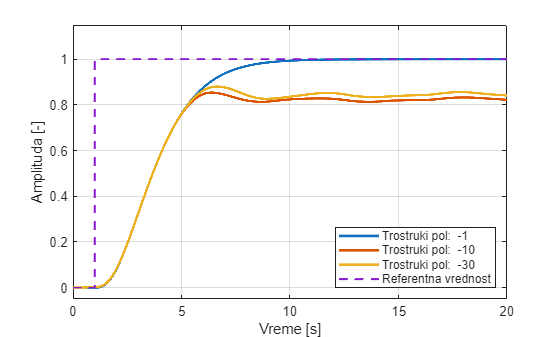

close all;
reg_type = 1; % 1 - cont. , 0 - disc
sat_off = 0; % 1 - off, 0 - on


ps = [-1, -10, -30];
for p = ps
    K = acker(A, B, [p, p, p]);
    [y, u, d, r, t] = simulate_step_input(1, 0, 1);
    plot(t, y(:, 1), "LineWidth", 2, "DisplayName", "Trostruki pol:  " + num2str(p)); hold on;
end



plot(t, r, "LineStyle", "--", "LineWidth", 1.5, "DisplayName", "Referentna vrednost"); %Referentna vrednost
xlabel("Vreme [s]");
ylabel("Amplituda [-]");
grid on; legend show; legend("Location","southeast") 
ylim([-0.05 1.15])

### Funkcije

function [y, u, d, r, t] = simulate_step_input(R0, D0, noise)
   
    mdl = "state_reg_mdl";
    %open_system(mdl);
    set_param(mdl + "/Step", "After", num2str(R0));
    set_param(mdl + "/Step1", "After", num2str(D0));
    set_param(mdl + "/n", "Gain", num2str(noise))
    out = sim(mdl);

    y = transpose(squeeze(out.y(1,:, :)));
    u = transpose(squeeze(out.u));
    d = out.d;
    r = out.r;
    t = out.tout(:, 1);
    
end